# Connect Poses Using ReedsShepp Connection Path

Create a `reedsSheppConnection` object.

reedsConnObj = reedsSheppConnection;

Define start and goal poses as `[x y theta]` vectors.

startPose = [0 0 0];
goalPose = [1 1 -pi];

Calculate a valid path segment to connect the poses.

[pathSegObj,pathCosts] = connect(reedsConnObj,startPose,goalPose);

Show the generated path.

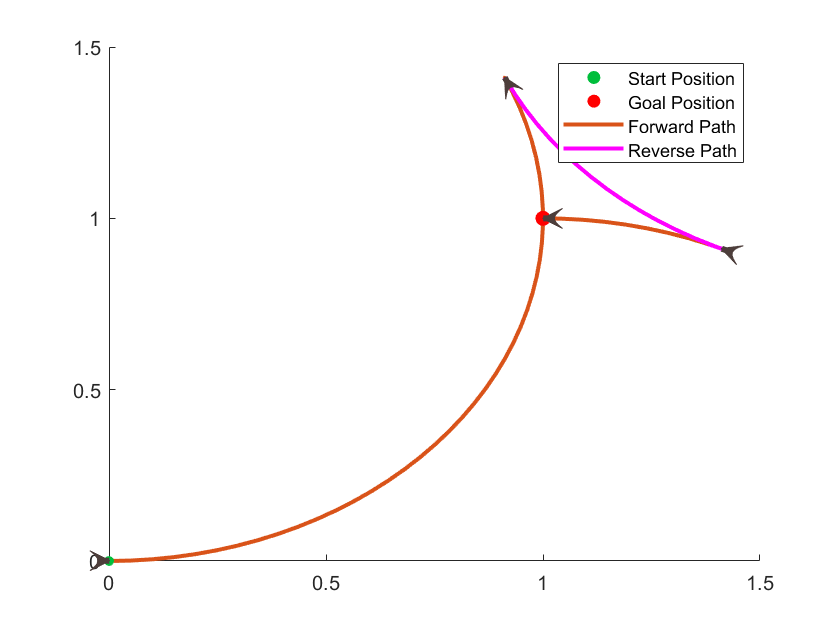

show(pathSegObj{1})

xlim('auto')
ylim('auto')

length = pathSegObj{1}.Length;
poses = interpolate(pathSegObj{1},0:0.1:length)

poses =          0         0         0
    0.0998    0.0050    0.1000
    0.1987    0.0199    0.2000
    0.2955    0.0447    0.3000
    0.3894    0.0789    0.4000
    0.4794    0.1224    0.5000
    0.5646    0.1747    0.6000
    0.6442    0.2352    0.7000
    0.7174    0.3033    0.8000
    0.7833    0.3784    0.9000


MotionLength = pathSegObj{1}.MotionLengths;
Interpolate = pathSegObj{1}.interpolate;
MotionDirections = pathSegObj{1}.MotionDirections;

j = 1;
for i = 1: size(poses,1)
    poses(i,4) = MotionDirections(j);
    if poses(i,1)==Interpolate(j+1,1) && poses(i,2)==Interpolate(j+1,2)
        j = j + 1;
    end
end
poses

poses =          0         0         0    1.0000
    0.0998    0.0050    0.1000    1.0000
    0.1987    0.0199    0.2000    1.0000
    0.2955    0.0447    0.3000    1.0000
    0.3894    0.0789    0.4000    1.0000
    0.4794    0.1224    0.5000    1.0000
    0.5646    0.1747    0.6000    1.0000
    0.6442    0.2352    0.7000    1.0000
    0.7174    0.3033    0.8000    1.0000
    0.7833    0.3784    0.9000    1.0000


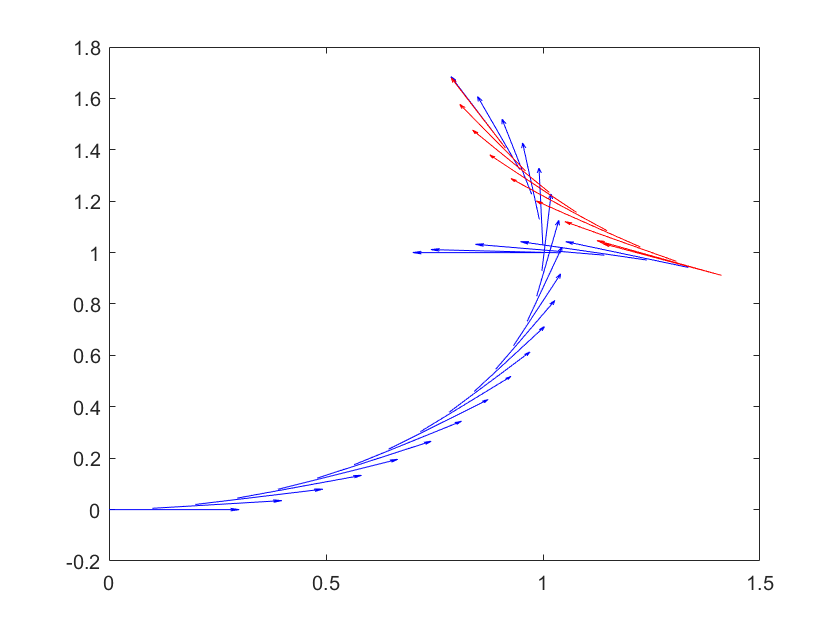

Error using matlab.internal.editor.figure.SerializedFigureState/serialize
Error while evaluating Figure SizeChangedFcn.




for i = 1: size(poses,1)
    if poses(i,4) == 1
        color  = '-b';
    else
        color = '-r';
    end
     quiver(poses(i,1),poses(i,2),cos(poses(i,3)),sin(poses(i,3)),0.3,color)
     drawnow
     hold on
end

*Copyright 2019 The MathWorks, Inc.*